# Blockkurs Tutorial 2: Digitale Signalverarbeitung

Copyright © 2024

Authors: J. Christopher Edgar and Gregory A. Miller

*The authors of the digital signal processing courseware are indebted to Prof. Bruce Carpenter (University of Illinois Urbana-Champaign). Bruce inspired the creation of this courseware, consulted with the authors throughout its development, and provided the original versions of the code and text for several sections, including those on complex numbers and normal distributions. Dr. J. Christohper Edgar is Professor of Radiology at the University of Pennsylvania and the Children’s Hospital of Philadelphia. Dr. Gregory A. Miller is Professor of Psychology at the University of California Los Angeles and University of Illinois Urbana-Champaign. The original courseware was written in Python and run using Juypter, available via GitHub. The adaptation of sections of this courseware to MATLAB was completed by Arne Hansen.*

**1. Wichtige Konzepte zu digitalen Signalen**

**    1.1 Sinuswellen**

    **1.2 Frequenz**

    **1.3 Amplitude**

    **1.4 Phase**

**2. Daten und Ordner**

## **1. Wichtige Konzepte zu digitalen Signalen**

Dieses Tutorial behandelt die Grundlagen der digitalen Signalverarbeitung, beginnend mit den grundlegenden Konzepten von digitalen Signalen. Wir werden anhand von **Sinuswellen** lernen, was die **Frequenz**, **Amplitude** und **Phase** eines Signals sind. Ihr müsst euch keine Gleichungen merken und auch nichts auswendig lernen. Versucht einfach anhand der Beispiele die oben genannten Kernkonzepte der digitalen Signalverarbeitung zu verstehen. 

## **1.1 Sinuswellen**

Eine Sinuswelle ist eine fundamentale Signalform, die durch die Gleichung y(t) = A * sin(2 * pi * f * t + phase) beschrieben wird. Hierbei ist:

    **A** die Amplitude,

    **f** die Frequenz,

    **phase** die Phase, und

    **t** die Zeit.

Das sieht nun erst mal sehr kompliziert aus. Wir werden uns jedoch im Folgenden vereinzelt mit den Bestandteilen dieser Gleichung auseinandersetzen.

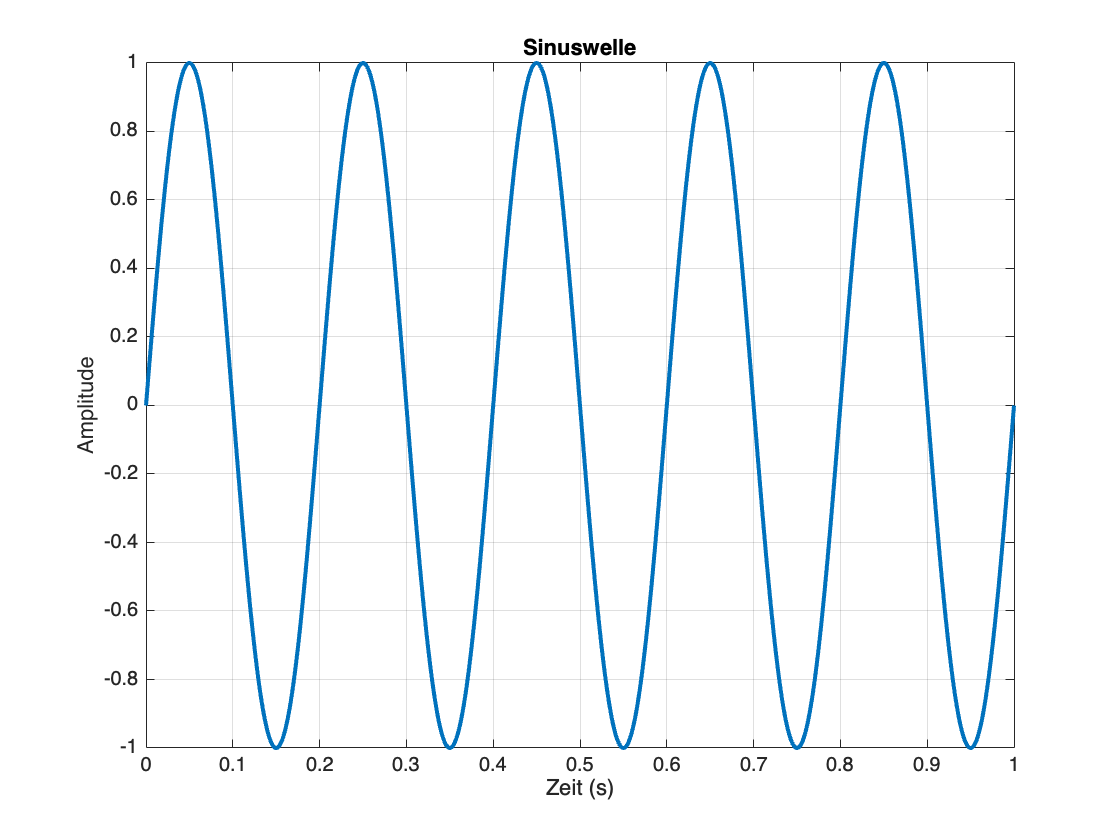

% MATLAB-Code zur Visualisierung einer Sinuswelle
t = 0:0.001:1; % Zeitvektor von 0 bis 1 Sekunde in Schritten von 1ms (0.001s)
f = 5; % Frequenz der Sinuswelle (Hz)
A = 1; % Amplitude

y = A * sin(2 * pi * f * t);

figure;
plot(t, y, 'LineWidth', 2);
title('Sinuswelle');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on; % Bewirkt lediglich das Einblenden von Gitternetzlinien

## **1.2 Frequenz**

Die Frequenz eines Signals beschreibt, wie oft eine Schwingung pro Sekunde auftritt. Sie wird in Hertz (Hz) gemessen.

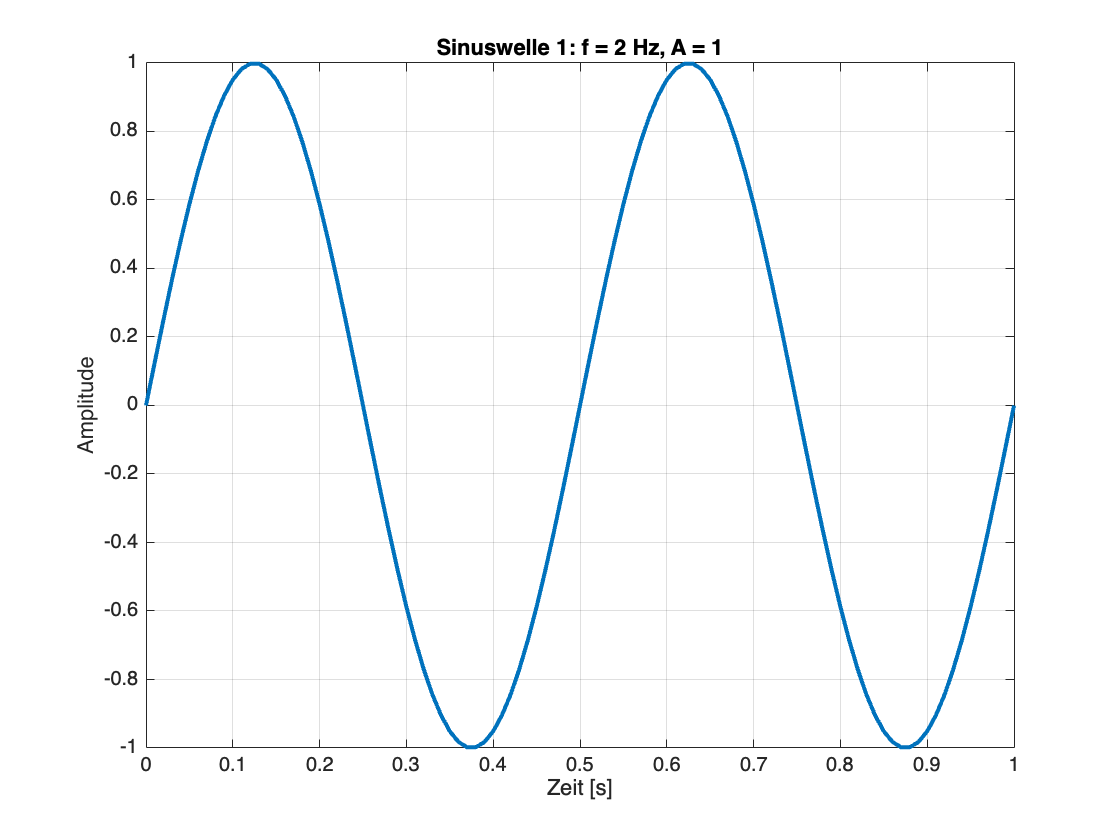

%% Parameter festlegen
f1 = 2; % Frequenz der ersten Sinuswelle in Hz
A1 = 1; % Amplitude der ersten Sinuswelle

t = 0:0.01:1; % Zeitvektor von 0 bis 2 Sekunden in Schritten von 10ms (0.01s)

%% Sinuswellen berechnen
y1 = A1 * sin(2 * pi * f1 * t); % Erste Sinuswelle

% Erste Sinuswelle plotten
figure;
plot(t, y1, 'LineWidth', 2);
xlabel('Zeit [s]');
ylabel('Amplitude');
title('Sinuswelle 1: f = 2 Hz, A = 1');
grid on;

## 1.3 Amplitude

Die Amplitude eines Signals gibt die maximale Auslenkung des Signals von seiner Gleichgewichtslage an. Sie bestimmt, wie "stark" das Signal ist.

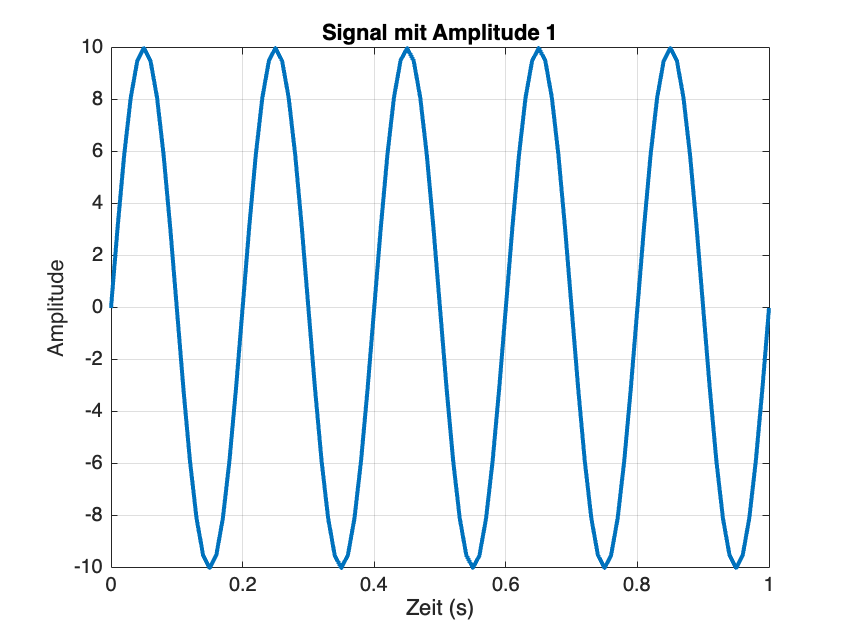

% MATLAB-Code zur Visualisierung von Signalen mit unterschiedlicher Amplitude
A1 = 10;

y1 = A1 * sin(2 * pi * f * t);

figure;
plot(t, y1, 'LineWidth', 2);
title('Signal mit Amplitude 1');
xlabel('Zeit (s)');
ylabel('Amplitude');
grid on;

hold on; % bewirkt dass wir ein zweites Signal im selben Plot darstellen können
% HIER ZWEITE SINUSWELLE MIT ANDERER AMP

## 1.4 Phase

Die Phase eines Signals beschreibt die Verschiebung der Sinuswelle entlang der Zeitachse. Sie wird in Radianten angegeben. 

**RADIANTEN WEG; DAS IST ZU KOMPLéIOZIERT**

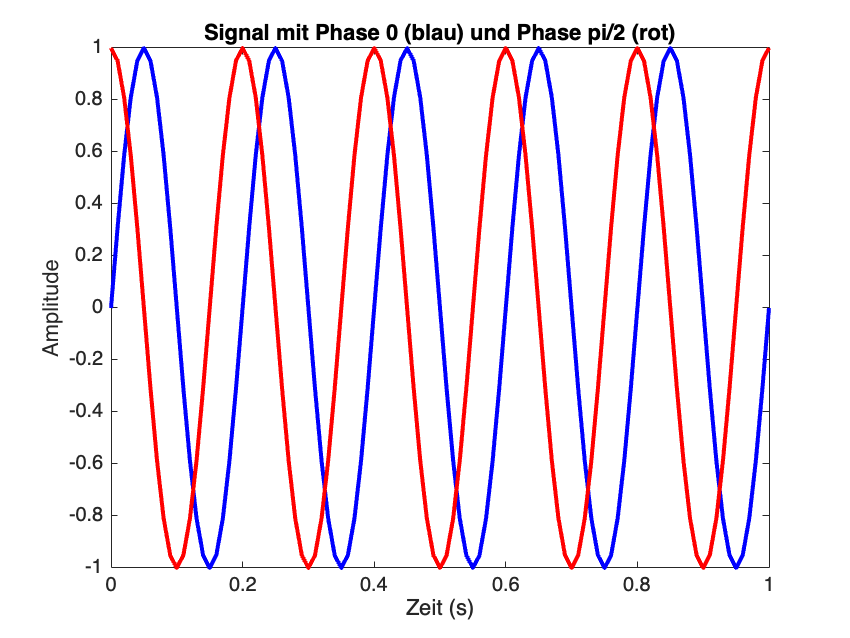

% MATLAB-Code zur Visualisierung von Signalen mit unterschiedlicher Phase
phi1 = 0; % Phase 0 Radianten
phi2 = pi/2; % Phase pi/2 Radianten

y1 = sin(2 * pi * f * t + phi1);
y2 = sin(2 * pi * f * t + phi2);

figure;
plot(t, y1, 'b', 'LineWidth', 2);
hold on
plot(t, y2, 'r', 'LineWidth', 2);
title('Signal mit Phase 0 (blau) und Phase pi/2 (rot)');
xlabel('Zeit (s)');
ylabel('Amplitude');